alpha =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans = 1.6331e+16

theta = 0.0648

v =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


beta =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


dt = 1.0000e-03

J = 0.0505

r = 0.2000

k = 101

k = 201

ans = -3.0490e-04

ans =    -0.1000   -0.0990   -0.0980   -0.0970   -0.0960   -0.0950   -0.0940   -0.0930   -0.0920   -0.0910   -0.0900   -0.0890   -0.0880   -0.0870   -0.0860   -0.0850   -0.0840   -0.0830   -0.0820   -0.0810   -0.0800   -0.0790   -0.0780   -0.0770   -0.0760   -0.0750   -0.0740   -0.0730   -0.0720   -0.0710   -0.0700   -0.0690   -0.0680   -0.0670   -0.0660   -0.0650   -0.0640   -0.0630   -0.0620   -0.0610   -0.0600   -0.0590   -0.0580   -0.0570   -0.0560   -0.0550   -0.0540   -0.0530   -0.0520   -0.0510


alpha =          0    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0008    0.0009    0.0011    0.0013    0.0015    0.0018    0.0020    0.0023    0.0025    0.0028    0.0031    0.0034    0.0038    0.0041    0.0045    0.0048    0.0052    0.0056    0.0061    0.0065    0.0069    0.0074    0.0079    0.0084    0.0089    0.0094    0.0099    0.0105    0.0110    0.0116    0.0122    0.0128    0.0134    0.0140    0.0146    0.0153    0.0159    0.0166    0.0173    0.0180


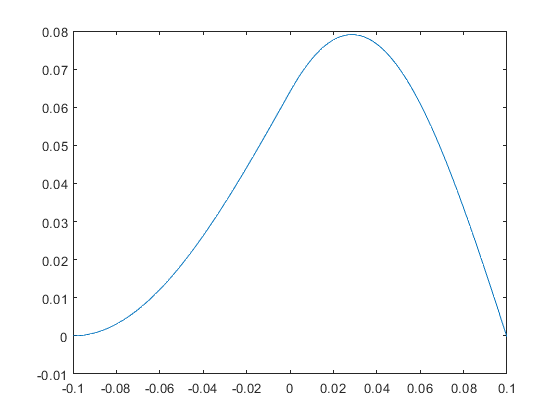

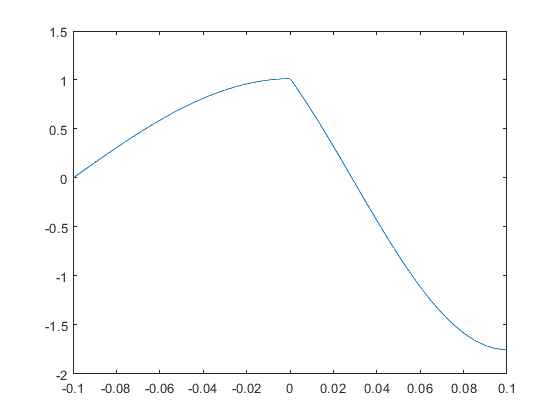

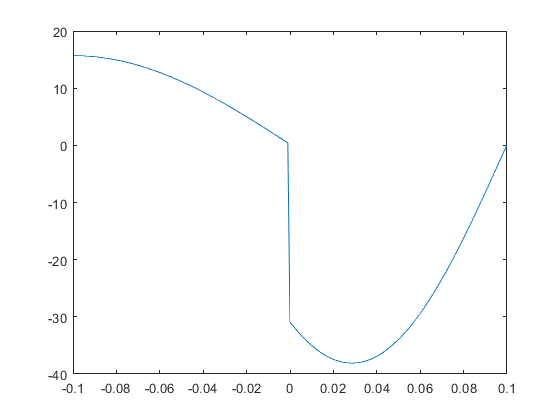

%6

alpha=zeros(1,201)
tan(pi/2)
theta=3.71/180*pi
v=zeros(1,201)
beta=zeros(1,201)
dt=0.001
J=0.05052
r=0.2
for k=1:100
    beta(k)=(61.2293*r*sin(theta-atan(tan(alpha(k))/sqrt(1+alpha(k)*alpha(k))))-0*r*sin(theta+atan(tan(alpha(k))/sqrt(1+alpha(k)*alpha(k)))))/J;
    v(k+1)=v(k)+beta(k)*dt;
    alpha(k+1)=alpha(k)+v(k)*dt+beta(k)*dt*dt/2;
end
k=101
beta(k)=(61.2293*r*sin(theta-atan(tan(alpha(k))/sqrt(1+alpha(k)*alpha(k))))-0*r*sin(theta+atan(tan(alpha(k))/sqrt(1+alpha(k)*alpha(k)))))/J;
for k=101:200
    beta(k)=(61.2293*r*sin(theta-atan(tan(alpha(k))/sqrt(1+alpha(k)*alpha(k))))-61.2293*r*sin(theta+atan(tan(alpha(k))/sqrt(1+alpha(k)*alpha(k)))))/J;
    v(k+1)=v(k)+beta(k)*dt;
    alpha(k+1)=alpha(k)+v(k)*dt+beta(k)*dt*dt/2;
end
k=201
alpha(end)
beta(k)=(61.2293*r*sin(theta-atan(tan(alpha(k))/sqrt(1+alpha(k)*alpha(k))))-61.2293*r*sin(theta+atan(tan(alpha(k))/sqrt(1+alpha(k)*alpha(k)))))/J;
-0.1:0.001:0.1
alpha
plot(-0.1:0.001:0.1,alpha)
plot(-0.1:0.001:0.1,v)
plot(-0.1:0.001:0.1,beta)